# RBF NN Supervisory Control - Single Joint Robotic Arm

clear; 
close all;

Single Joint Robotic Arm


$$G(s) = \frac{1}{LMs^3 + s^2LB + s^2RM + sLN + sK_B + sRB + RN)$$


## Physical Parameter Initialization

% Physical Parameter Definition

J = 3.2284E-6;      % Rotor inertia (kg.m^2)
B_0 = 3.5077E-6;    % coefficient of viscous friction at the joint (Nms)
Kb = 0.0274;        % electromotive force constant (V/rad/sec)
Kt = 0.0274;        % motor torque constant (Nm/Amp)
R = 4;              % armature resistance (ohm)
L = 2.75E-6;        % armature inductance (H)

L_0 = 0.1;      % Link length (m)
m = 0.01;       % mass (kg) of the link
G = 9.8;        % Gravity Coeficient (m/s^2)
M_0 = 0.01;     % Load Mass (kg)
R_0 = 0.025;    % Radius of the Load (m)

M = (J/Kt) + ((m*L_0^2)/(3*Kt)) + ((M_0*L_0^2)/Kt) + ((2*M_0*R_0^2)/(5*Kt));
N = ((m*L_0*G) / (2*Kt)) + ((M_0*L_0*G)/Kt);
B = B_0/Kt;

## Transfer Function

s-Domain Open Loop 

dt = 0.0001;          % sample time 0.1ms

s = tf('s');
G = 1 / (s^3*L*M + s^2*L*B + s^2*R*M + s*L*N +s*Kb + s*R*B + R*N)

G =
 
                        1
  ----------------------------------------------
  1.396e-08 s^3 + 0.0203 s^2 + 0.02791 s + 2.146
 
Continuous-time transfer function.
Model Properties


Convert transfer function to z-domain

Gz = c2d(G, dt, 'tustin')     % convert to z-domain

Gz =
 
  1.215e-07 z^3 + 3.644e-07 z^2 + 3.644e-07 z + 1.215e-07
  -------------------------------------------------------
            z^3 - 1.027 z^2 - 0.9457 z + 0.9727
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


Gz.variable = 'z^-1'            % inverse z-transform

Gz =
 
  1.215e-07 + 3.644e-07 z^-1 + 3.644e-07 z^-2 + 1.215e-07 z^-3
  ------------------------------------------------------------
           1 - 1.027 z^-1 - 0.9457 z^-2 + 0.9727 z^-3
 
Sample time: 0.0001 seconds
Discrete-time transfer function.
Model Properties


[num, den] = tfdata(Gz, 'v')

num = 1.0e-06 *

    0.1215    0.3644    0.3644    0.1215


den =     1.0000   -1.0270   -0.9457    0.9727


## PD Control Only

### Parameters Initialization

t = 0:dt:0.2;   % Simualtion Time

% step input
yd = ones(size(t));
yd(1) = 0;

% output variable
yp = zeros(size(t));     % with only PD Controller

% initial conditions
yk_1 = 0;
yk_2 = 0;
yk_3 = 0;
ydk_1 = 0;
ydk_2 = 0;
ydk_3 = 0;

ek_1 = 0;               % intial value of error
e = zeros(size(t));     % error vector  for RBF
up = zeros(size(t));    % PD controller output vector

% PD Parameters from Root Locus Controller Design
kp = 44.5;
kd = 13.4;

### Calculating output of system with only PD Controller

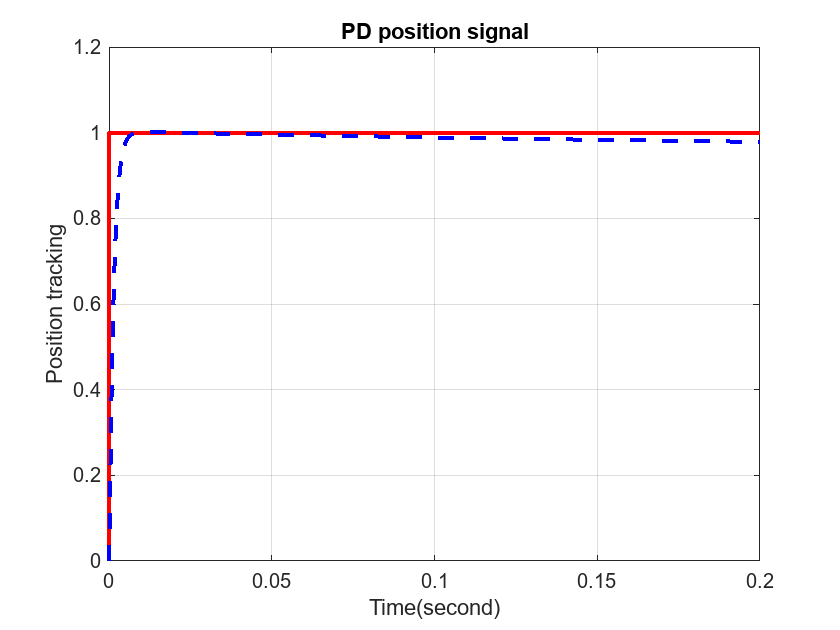

% solving difference equation
for i = 1:length(t)
    if i == 1
        e(i) = yd(i) - yk_1;     % error
        up(i) = kp*e(i) + kd*((e(i) - ek_1)/dt);    % PD Controller
        uterms = num(1)*up(i) + num(2)*ydk_1 + num(3)*ydk_2 + num(4)*ydk_3;
        yterms = -den(2)*yk_1 - den(3)*yk_2 - den(4)*yk_3;
        yp(i) = uterms + yterms;
    elseif i == 2
        e(i) = yd(i) - yp(i-1);     % error
        up(i) = kp*e(i) + kd*((e(i) - e(i-1))/dt);    % PD Controller
        uterms = num(1)*up(i) + num(2)*up(i-1) + num(3)*ydk_1 + num(4)*ydk_2;
        yterms = -den(2)*yp(i-1) - den(3)*yk_1 - den(4)*yk_2;
        yp(i) = uterms + yterms;
    elseif i == 3
        e(i) = yd(i) - yp(i-1);     % error
        up(i) = kp*e(i) + kd*((e(i) - e(i-1))/dt);    % PD Controller
        uterms = num(1)*up(i) + num(2)*up(i-1) + num(3)*up(i-2) + num(4)*ydk_1;
        yterms = -den(2)*yp(i-1) - den(3)*yp(i-2) - den(4)*yk_3;
        yp(i) = uterms + yterms;
    else
        e(i) = yd(i) - yp(i-1);     % error
        up(i) = kp*e(i) + kd*((e(i) - e(i-1))/dt);    % PD Controller
        uterms = num(1)*up(i) + num(2)*up(i-1) + num(3)*up(i-2) + num(4)*up(i-3);
        yterms = -den(2)*yp(i-1) - den(3)*yp(i-2) - den(4)*yp(i-3);
        yp(i) = uterms + yterms;
    end
end

plot(t,yd,'r', t, yp, 'b--', 'linewidth',2);
grid on;
xlabel('Time(second)'); ylabel('Position tracking');
title('PD position signal')

## RBF Supervisory Control

### Parameter Initialization

t = 0:dt:0.2;   % Simualtion Time

% output variable
y = zeros(size(t));     % with RBF

% step input
yd = ones(size(t));
yd(1) = 0;

% initial conditions
yk_1 = 0;
yk_2 = 0;
yk_3 = 0;
ydk_1 = 0;
ydk_2 = 0;
ydk_3 = 0;

ek_1 = 0;               % intial value of error
e = zeros(size(t));     % error vector  for RBF
up = zeros(size(t));    % PD controller output vector

h_l = 4;                % number of hidden layers
h = zeros(1,h_l);       % radial basis vector
H = zeros(length(t), h_l);  % output of hidden neural net
un = zeros(size(t));    % RBF output vector

% intial variables            
xi = 0;                   
b = 0.5*ones(h_l,1);    % vector b - width of Gaussian Function
c = [-4 -2 2 4];        % coordinate valve of center point of Gaussian Function

w = rand(h_l,1);       % weight vector of RBF
w_1 = w;
w_2 = w_1;
W = zeros(length(t),h_l);  % Weight Vector

xite = 0.30;            % learning rate
alfa = 0.05;            % momentum factor

% PD Parameters from Root Locus Controller Design
kp = 44.5;
kd = 13.4;

### Calculating output of system with RBF Supervisory Control

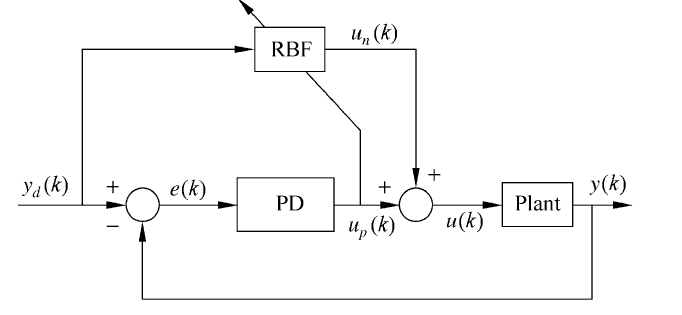

for k = 1:1:length(t)
    if k == 1
        e(k) = yd(k) - ydk_1;     % error
        up(k) = kp*e(k) + kd*((e(k) - ek_1)/dt);    % PD Controller

        xi = yd(k);     % input to the RBF
        % calculating RB vector
        for j=1:1:h_l
            h(j) = exp(-norm(xi-c(:,j))^2/(2*b(j)*b(j)));
        end
        un(k) = w'*h';      % output of the RBF
        u(k) = up(k) + un(k);   % updated plant input with RBF + PD controller
        
        % calculating output of the system with RBF
        uterms = num(1)*u(k) + num(2)*ydk_1 + num(3)*ydk_2 + num(4)*ydk_3;
        yterms = -den(2)*yk_1 - den(3)*yk_2 - den(4)*yk_3;
        y(k) = uterms + yterms;

    elseif k == 2
        e(k) = yd(k) - y(k-1);     % error
        up(k) = kp*e(k) + kd*((e(k) - e(k-1))/dt);    % PD Controller

        xi = yd(k);     % input to the RBF
        % calculating RB vector
        for j=1:1:h_l
            h(j) = exp(-norm(xi-c(:,j))^2/(2*b(j)*b(j)));
        end
        un(k) = w'*h';      % output of the RBF
        u(k) = up(k) + un(k);   % updated plant input with RBF + PD controller
        
        % calculating output of the system with RBF
        uterms = num(1)*u(k) + num(2)*u(k-1) + num(3)*ydk_1 + num(4)*ydk_2;
        yterms = -den(2)*y(k-1) - den(3)*yk_1 - den(4)*yk_2;
        y(k) = uterms + yterms;

    elseif k == 3
        e(k) = yd(k) - y(k-1);     % error
        up(k) = kp*e(k) + kd*((e(k) - e(k-1))/dt);    % PD Controller

        xi = yd(k);     % input to the RBF
        % calculating RB vector
        for j=1:1:h_l
            h(j) = exp(-norm(xi-c(:,j))^2/(2*b(j)*b(j)));
        end
        un(k) = w'*h';      % output of the RBF
        u(k) = up(k) + un(k);   % updated plant input with RBF + PD controller
        
        % calculating output of the system with RBF
        uterms = num(1)*u(k) + num(2)*u(k-1) + num(3)*u(k-2) + num(4)*ydk_1;
        yterms = -den(2)*y(k-1) - den(3)*y(k-2) - den(4)*yk_3;
        y(k) = uterms + yterms;

    else
        e(k) = yd(k) - y(k-1);     % error
        up(k) = kp*e(k) + kd*((e(k) - e(k-1))/dt);    % PD Controller

        xi = yd(k);     % input to the RBF
        % calculating RB vector
        for j=1:1:h_l
            h(j) = exp(-norm(xi-c(:,j))^2/(2*b(j)*b(j)));
        end
        un(k) = w'*h';      % output of the RBF
        u(k) = up(k) + un(k);   % updated plant input with RBF + PD controller
        
        % calculating output of the system with RBF
        uterms = num(1)*u(k) + num(2)*u(k-1) + num(3)*u(k-2) + num(4)*u(k-3);
        yterms = -den(2)*y(k-1) - den(3)*y(k-2) - den(4)*y(k-3);
        y(k) = uterms + yterms;
    end
    
    % Creating the vector for Gaussian Function % Hidden Layer weights
    H(k) = h(j);        
    W(k,:) = w';
    
    %Update NN Weight
    d_w = -xite*(un(k)-u(k))*h';
    w = w_1 + d_w + alfa*(w_1 - w_2);
    w_2 = w_1;
    w_1 = w;
end

## Simulation Results

Comparision between RBF Supervisory Control and only PD Controller

- Tracking with RBF is much better than PD Controller with a bit of overshoot in the beginning

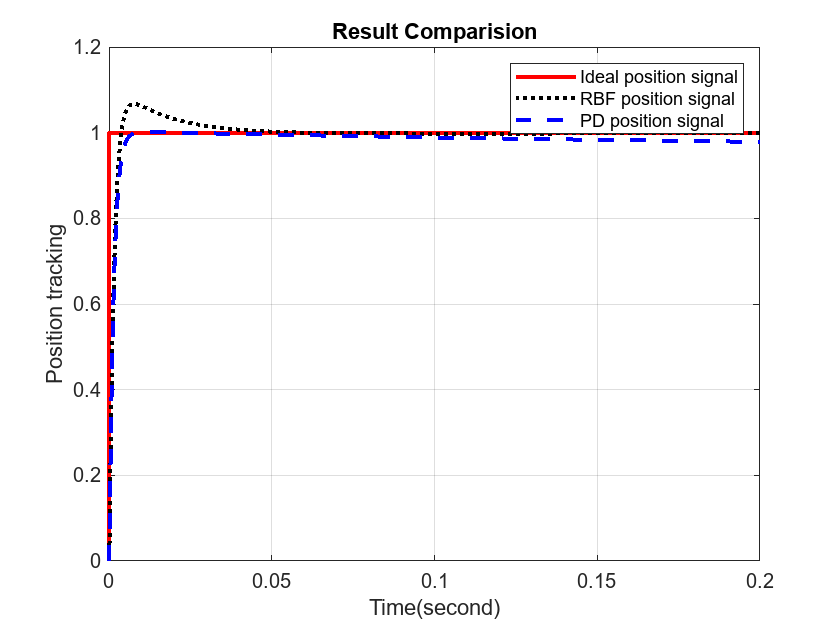

plot(t,yd,'r',t,y,'k:', t, yp, 'b--', 'linewidth',2);
grid on;
xlabel('Time(second)');ylabel('Position tracking');
legend('Ideal position signal','RBF position signal', 'PD position signal');
title('Result Comparision')

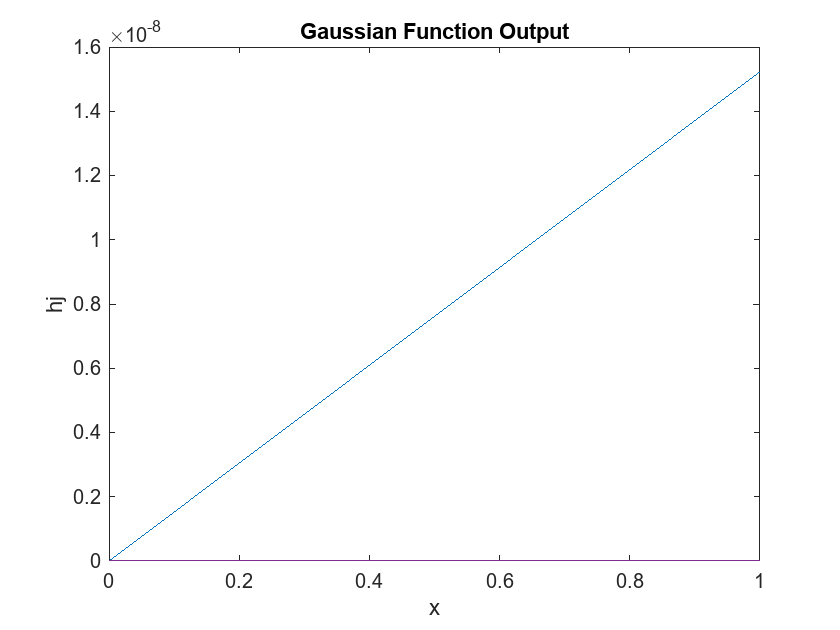



plot(yd, H(:, 1), yd, H(:, 2), yd, H(:, 3), yd, H(:, 4));
xlabel('x');ylabel('hj');
title('Gaussian Function Output')